# Problem 1: Lead Compensator for Speed Improvement

a) Baseline PID Performance:

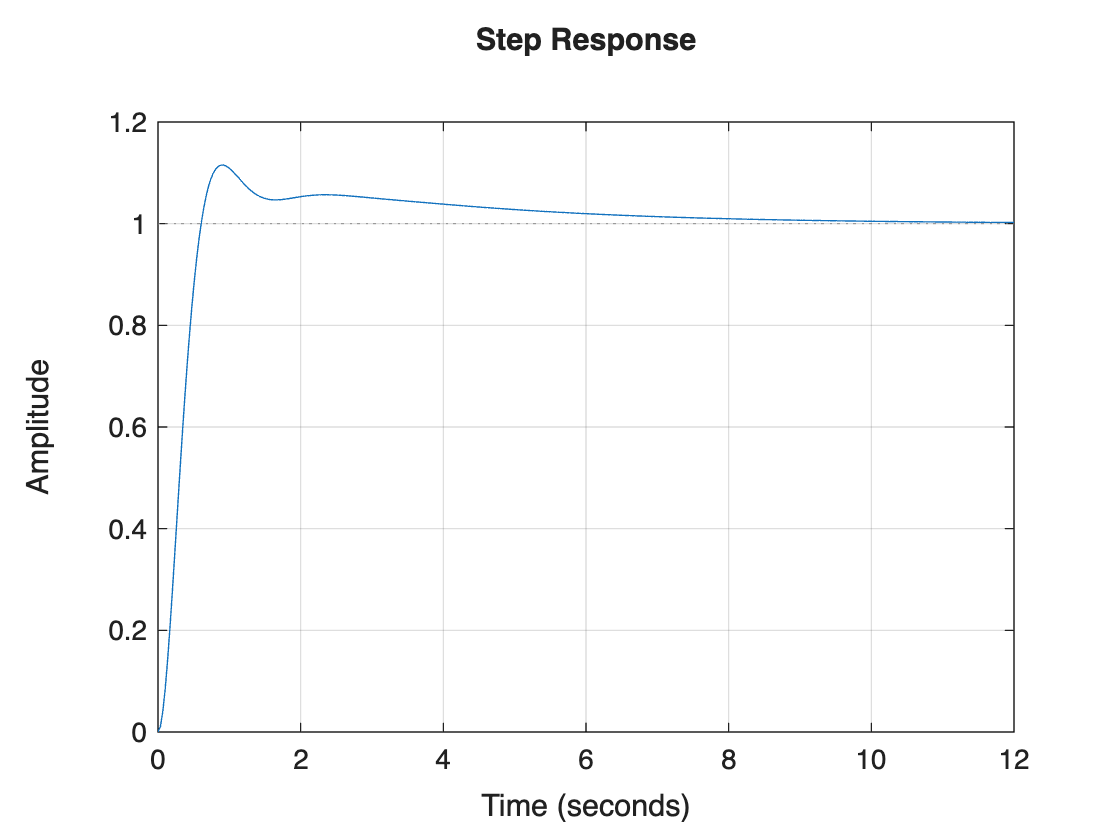

s = tf('s');
G = 20/(s*(s+2)*(s+5));
pidTuner(G,'PID');
Kp = 1.75;
Ki = 0.45042;
Kd = 1.0036;
Cpid = pid(Kp, Ki, Kd);
T = feedback(Cpid*G, 1);
step(T);
grid on;

info = stepinfo(T);
fprintf("Rise Time")

Rise Time

disp(info.RiseTime)

    0.4083



fprintf("Settling Time")

Settling Time

disp(info.SettlingTime)

    5.9510



fprintf("Overshoot")

Overshoot

disp(info.Overshoot)

   11.5372



b) Lead Compensator Design:

z = 3;
p = 15;
Kc_values = 9:0.5:13;

for Kc = Kc_values
    Clead = Kc*(s+3)/(s+15);
    Ctotal = Cpid*Clead;
    T = feedback(Ctotal*G,1);

    info = stepinfo(T);
    
    fprintf('Kc=%.2f | Tr=%.2f | Ts=%.2f | OS=%.2f%%\n', ...
        Kc, info.RiseTime, info.SettlingTime, info.Overshoot);
end

Kc=9.00 | Tr=0.16 | Ts=4.17 | OS=2.83%
Kc=9.50 | Tr=0.15 | Ts=3.96 | OS=2.69%
Kc=10.00 | Tr=0.15 | Ts=3.75 | OS=2.55%
Kc=10.50 | Tr=0.14 | Ts=3.55 | OS=2.43%
Kc=11.00 | Tr=0.13 | Ts=3.34 | OS=2.32%
Kc=11.50 | Tr=0.13 | Ts=3.12 | OS=3.28%
Kc=12.00 | Tr=0.12 | Ts=2.89 | OS=4.27%
Kc=12.50 | Tr=0.12 | Ts=2.61 | OS=5.21%
Kc=13.00 | Tr=0.11 | Ts=0.59 | OS=6.18%


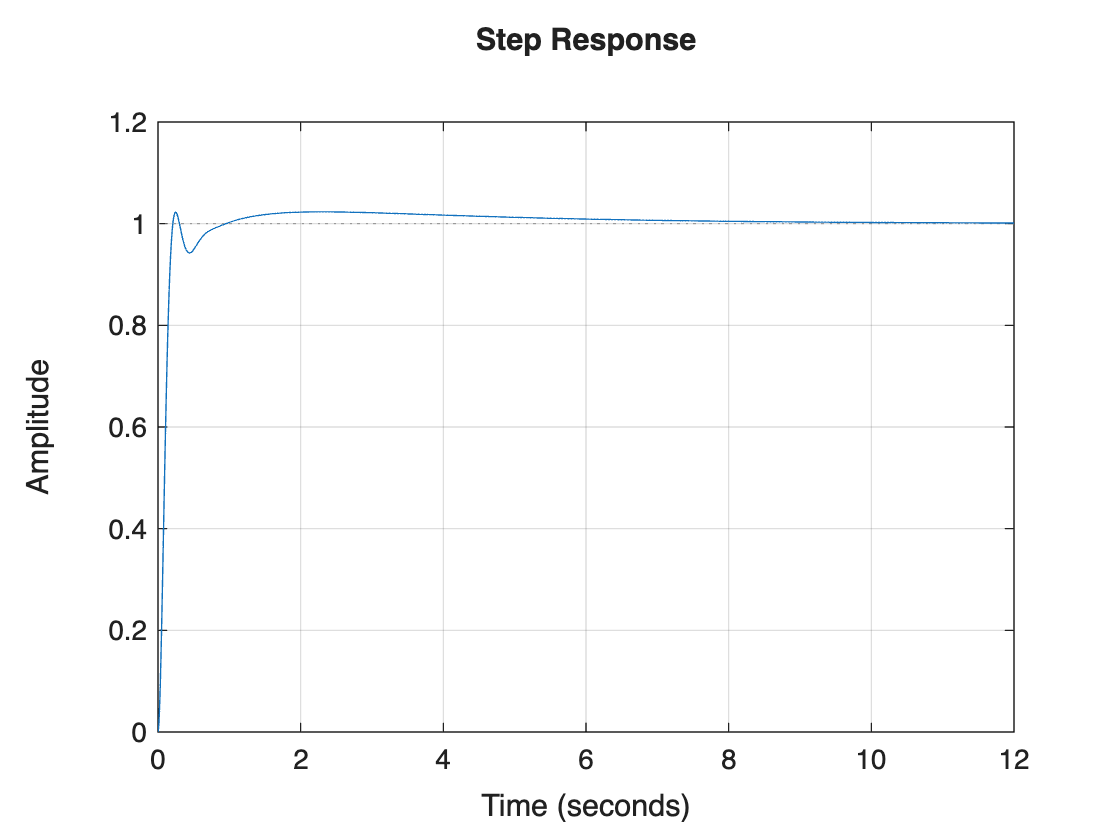

Kc = 11;
Clead = Kc*(s+z)/(s+p);
Ctotal = Cpid * Clead;
T = feedback(Ctotal*G,1);

step(T);
grid on

c) Performance Comparison:

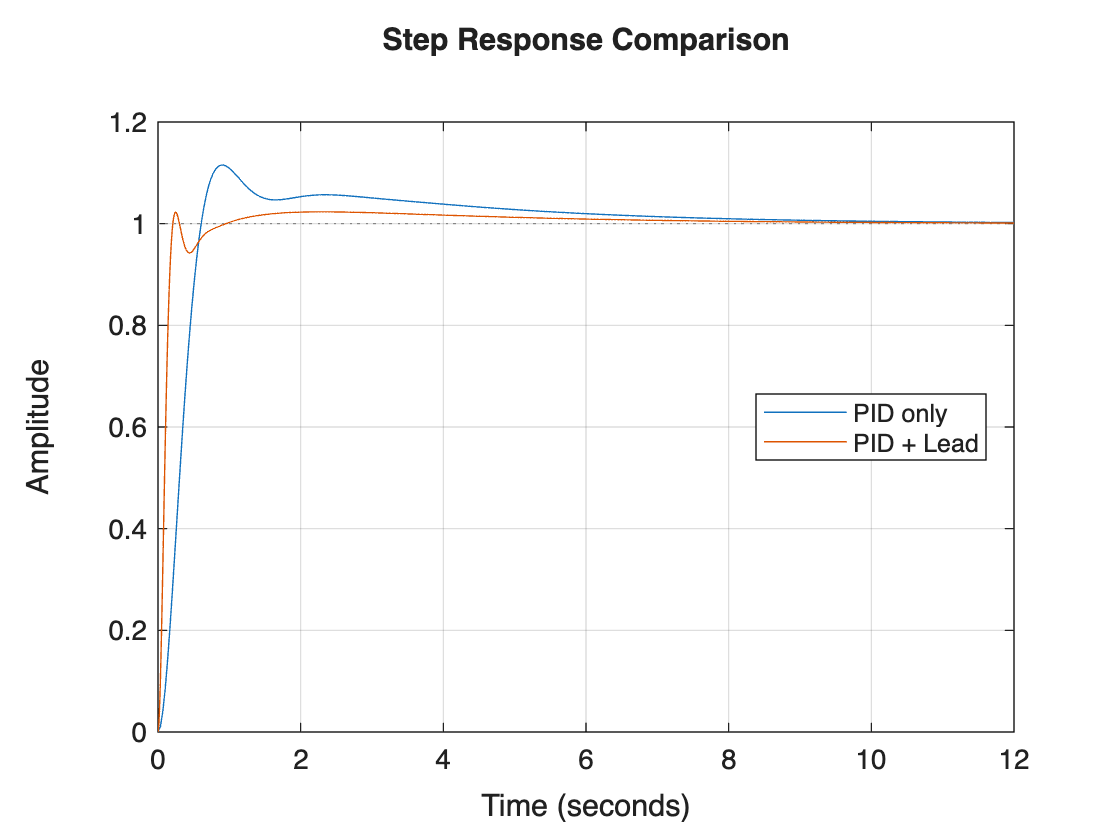

T_pid  = feedback(Cpid*G,1);
T_lead = feedback(Ctotal*G,1);

step(T_pid, T_lead)
grid on
legend('PID only','PID + Lead','Location','best')
title('Step Response Comparison')


info_pid  = stepinfo(T_pid,'SettlingTimeThreshold',0.02);
info_lead = stepinfo(T_lead,'SettlingTimeThreshold',0.02);

PerformanceTable = table( ...
    [info_pid.RiseTime; info_lead.RiseTime], ...
    [info_pid.SettlingTime; info_lead.SettlingTime], ...
    [info_pid.Overshoot; info_lead.Overshoot], ...
    'VariableNames', {'RiseTime_s','SettlingTime_s','Overshoot_pct'}, ...
    'RowNames', {'PID Only','PID + Lead'} ...
);
disp(PerformanceTable)

                  RiseTime_s    SettlingTime_s    Overshoot_pct
                  __________    ______________    _____________

    PID Only       0.40833           5.951           11.537    
    PID + Lead     0.13161          3.3383           2.3244    



The lead compensator significantly improved the transient response by **increasing the phase margin** of the closed-loop system. By introducing a zero closer to the origin than its pole, the lead compensator added **positive phase lead** near the gain crossover frequency.

This increase in phase margin improved the **damping** of the dominant closed-loop poles, which:

- Reduced oscillatory behavior

- Greatly decreased overshoot

- Allowed the system to settle more quickly

Additionally, the added phase lead enabled the use of **higher effective loop gain** without compromising stability. As a result, the dominant poles moved further left in the complex plane, leading to a much **faster rise time**.

Overall, the lead compensator reshaped the frequency response of the system to achieve **faster and better-damped dynamics**, as confirmed by the substantial reductions in rise time, settling time, and overshoot compared to the PID-only controller.

***One-liner:***

The lead compensator improved transient response by increasing phase margin, resulting in faster rise time, reduced settling time, and significantly lower overshoot.

d) Parameter Experimentation:

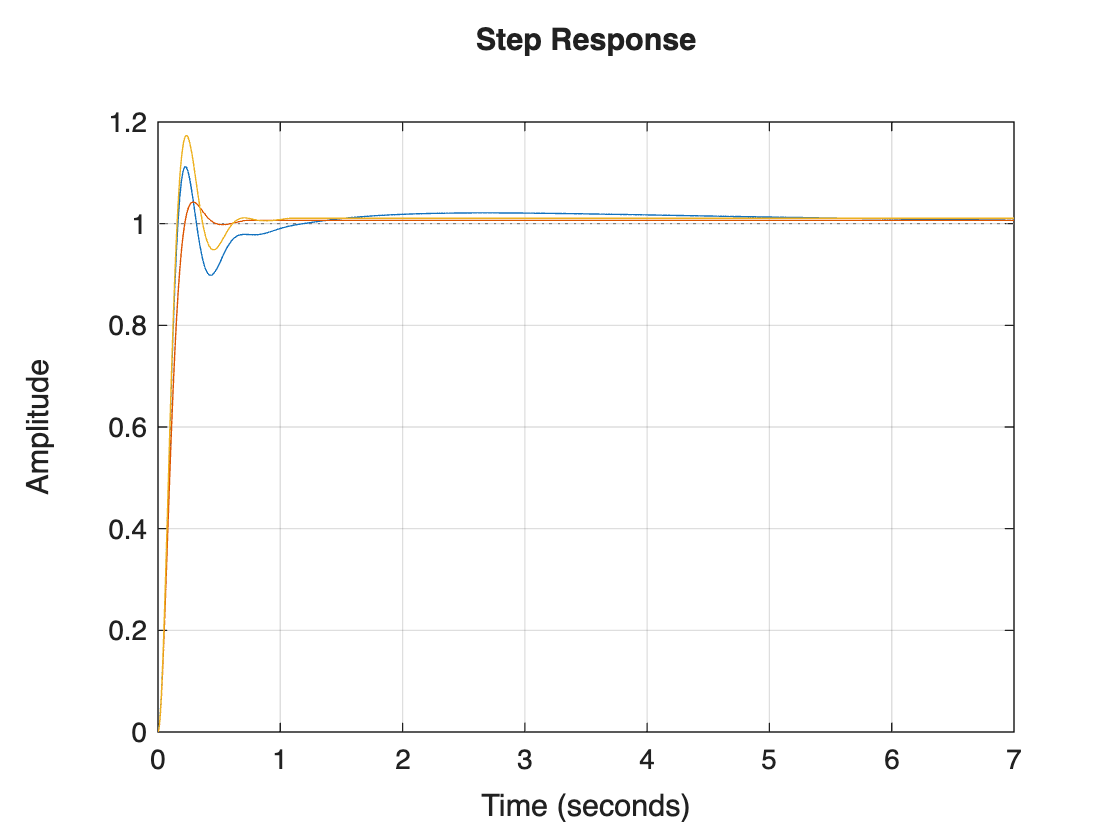

Kc = 11;
z1=2;
z2=5;
z3=4;
p1=10;
p2=20;
p3=12;
Clead1 = Kc*(s+z1)/(s+p1);
Ctotal1 = Cpid * Clead1;
T1 = feedback(Ctotal1*G,1);
Clead2 = Kc*(s+z2)/(s+p2);
Ctotal2 = Cpid * Clead2;
T2 = feedback(Ctotal2*G,1);
Clead3 = Kc*(s+z3)/(s+p3);
Ctotal3 = Cpid * Clead3;
T3 = feedback(Ctotal3*G,1);
step(T1)
hold on
step(T2)
hold on
step(T3)
hold off
grid on

Increasing the separation between the zero and pole and placing them at higher frequencies shifts the phase lead to higher frequencies, resulting in faster system response. However, more aggressive zero–pole placement can reduce damping and robustness. Therefore, the choice of zero and pole represents a trade-off between response speed and stability.

# Problem 2: Lag Compensator for Steady-State Accuracy

s = tf('s');
G = 50/((s+1)*(s+3)*(s+8));

a) Proportional Controller Analysis:

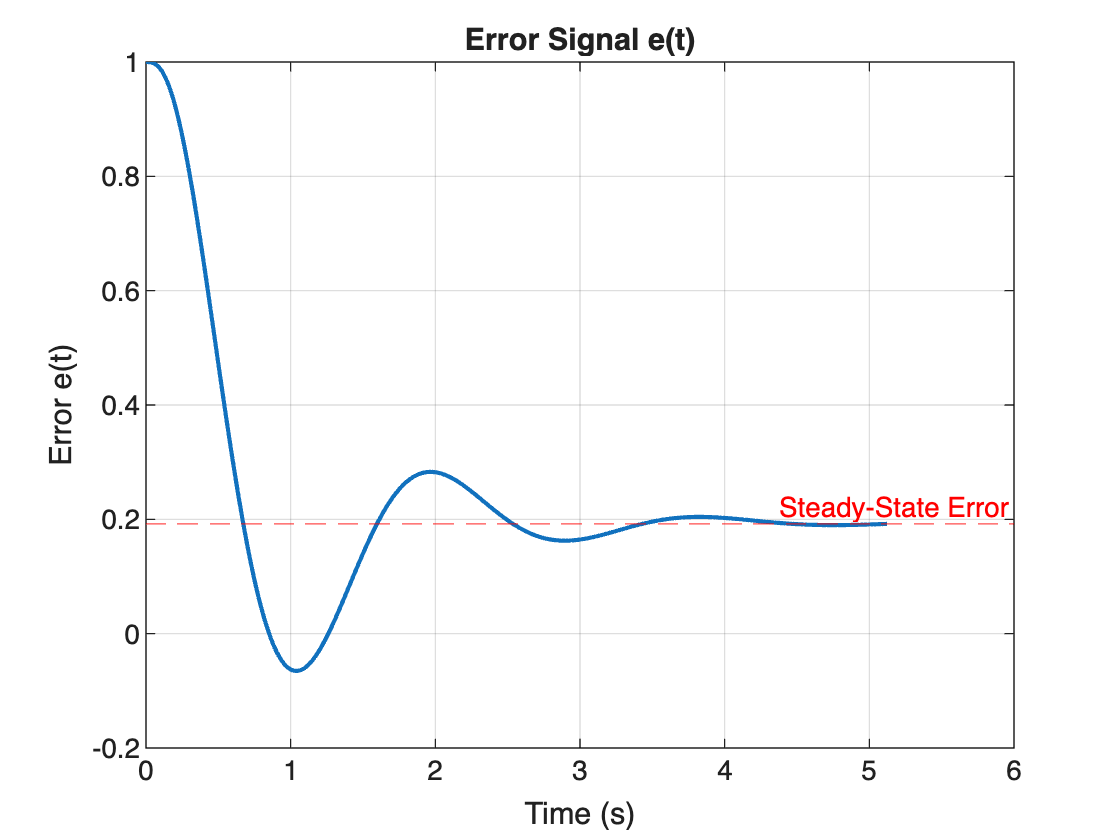

Kp = 2;
Cpid = pid(Kp,0,0);
T_new = feedback(Cpid*G, 1);
step(T_new);
grid on;
%steady-state error-
ess = abs(1 - dcgain(T_new));
hold on
yline(1,'r--','Reference')
yline(dcgain(T_new),'k--','Steady-State Output')
hold off
grid on
legend('System Output','Reference','Steady-State Value','Location','best')

[y,t] = step(T_new);
r = ones(size(t));   % unit step reference
e = r - y;           % error signal
figure
plot(t,e,'LineWidth',1.5)
grid on
xlabel('Time (s)')
ylabel('Error e(t)')
title('Error Signal e(t)')

% Mark steady-state error
yline(e(end),'r--','Steady-State Error')

b) Lag - Compensator

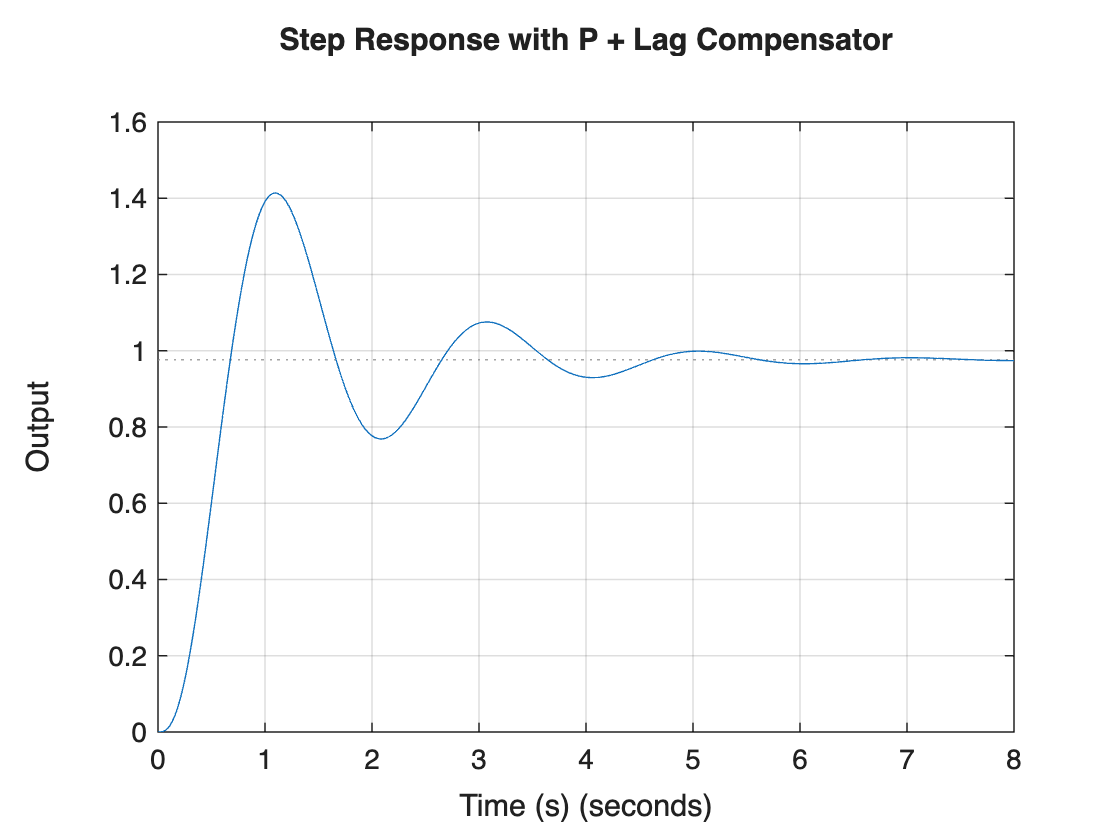

Kp = 2;
z = 1;
p = 0.1;
Kc = 1;

Clag = Kc*(s+z)/(s+p);

Ctotal = Kp * Clag;

T_lag = feedback(Ctotal*G, 1);

step(T_lag)
grid on
title('Step Response with P + Lag Compensator')
xlabel('Time (s)')
ylabel('Output')

c) Steady-State Error Reduction:

% P controller
Kp = 2;
Cp = pid(Kp,0,0);
T_p = feedback(Cp*G,1);

% P + Lag controller
Clag = (s+1)/(s+0.1);
C_plag = Kp * Clag;
T_plag = feedback(C_plag*G,1);

% Step information (2% settling time)
info_p    = stepinfo(T_p,'SettlingTimeThreshold',0.02);
info_plag = stepinfo(T_plag,'SettlingTimeThreshold',0.02);

% Steady-state errors (ess = |r_final - y_final|)
ess_p    = abs(1 - dcgain(T_p));
ess_plag = abs(1 - dcgain(T_plag));

% Error reduction percentage
err_reduction_pct = ((ess_p - ess_plag)/ess_p)*100;

% Create comparison table
SS_Error_Table = table( ...
    [ess_p; ess_plag], ...
    [info_p.SettlingTime; info_plag.SettlingTime], ...
    'VariableNames', {'SteadyStateError','SettlingTime_2pct_s'}, ...
    'RowNames', {'P Only','P + Lag'} ...
);
disp(SS_Error_Table)

               SteadyStateError    SettlingTime_2pct_s
               ________________    ___________________

    P Only          0.19355              3.2198       
    P + Lag        0.023438              5.2126       



fprintf('Error Reduction = %.2f %%\n', err_reduction_pct);

Error Reduction = 87.89 %


A lag compensator reduces steady-state error by increasing low-frequency gain

This means:

- Persistent (low-frequency) errors are amplified more strongly

- The output is driven closer to the reference value

- Steady-state error is significantly reduced

However, because the lag compensator introduces a pole close to the origin:

- System response becomes slower

- Settling time increases slightly

This trade-off—**better accuracy but slower response**—is the defining characteristic of lag compensation.

d) Trade off Analysis-

– Does settling time increase?

**Yes**

Adding a lag compensator introduces a **pole close to the origin**, which slows down system dynamics, Reduces bandwidth, causes the system to take longer to settle.

– Is the response slower?

**Yes**

compared to P-only control, the rise time increases, and system reacts slower to changes, ultimately, the response time is slower. 

% P + Lag (p = 0.1)
Clag1 = (s+1)/(s+0.1);
T_lag1 = feedback(Kp*Clag1*G,1);

% P + Lag (p = 0.01)
Clag2 = (s+1)/(s+0.01);
T_lag2 = feedback(Kp*Clag2*G,1);

% Step responses
step(T_p, T_lag1, T_lag2)
grid on
legend('P only','P + Lag (p=0.1)','P + Lag (p=0.01)','Location','best')

From this we conclude, Lag compensation improves accuracy at the expense of response speed, illustrating a trade-off between steady-state error reduction and transient performance.

# Problem 3: Feedforward + Feedback Control

a) Feedback-Only Control:

s = tf('s');
G = 1/(s + 0.5);
Kp = 2;
Ki = 1;
Cfb = Kp + Ki/s ;
T_r = feedback(Cfb*G, 1);
T_d = -feedback(G, Cfb); 
% Time vector
t = 0:0.01:20;
% Reference speed (constant)
r = ones(size(t));
% Disturbance (uphill at t = 5s)
d = 0.3 * (t >= 5);
% Output response
y_r = lsim(T_r, r, t);   % response to reference
y_d = lsim(T_d, d, t);   % response to disturbance
% Total output
y = y_r + y_d;
% Error signal
e = r - y;
figure

subplot(2,1,1)
plot(t, r, 'r--', 'LineWidth', 1.5)
hold on
plot(t, y, 'b', 'LineWidth', 1.5)
grid on
ylabel('Speed')
legend('Reference','Output','Location','best')
title('Feedback-Only Control (PI Controller)')

subplot(2,1,2)
plot(t, e, 'k', 'LineWidth', 1.5)
grid on
xlabel('Time (s)')
ylabel('Error')
% Index where disturbance starts
idx = t >= 5;

max_error = max(abs(e(idx)))

max_error = 0.0945

fprintf('Max Error:%.2f %%/n',max_error);

Max Error:0.09 %/n

% 2% error band
tol = 0.02;

% Recovery time calculation
recovery_idx = find(abs(e(idx)) <= tol, 1, 'first');

recovery_time = t(find(idx,1)-1 + recovery_idx) - 5

recovery_time = 0

fprintf('recover time:%.4f %%/n',recovery_time);

recover time:0.0000 %/n

b) Adding Feedforward Control:

Kff = 1/dcgain(G);
% Feedforward compensation
u_ff = Kff * d;
y_ff = lsim(G, u_ff, t);

% Total output
y = y_r + y_d + y_ff;

% Error
e = r - y;
figure

subplot(2,1,1)
plot(t, r, 'r--', 'LineWidth', 1.5)
hold on
plot(t, y, 'b', 'LineWidth', 1.5)
grid on
ylabel('Speed')
legend('Reference','Output','Location','best')
title('Feedback + Feedforward Control')

subplot(2,1,2)
plot(t, e, 'k', 'LineWidth', 1.5)
grid on
xlabel('Time (s)')
ylabel('Error')

c) Performance Comparison:

% Feedback-only response
y_r_fb = lsim(T_r,r,t);
y_d_fb = lsim(T_d,d,t);
y_fb = y_r_fb + y_d_fb;
e_fb = r - y_fb;
% Feedforward + feedback
u_ff = Kff*d;
y_ff = lsim(G,u_ff,t);
y_fffb = y_r_fb + y_d_fb + y_ff;
e_fffb = r - y_fffb;
%output comparision
figure
plot(t,y_fb,'b','LineWidth',1.5); hold on
plot(t,y_fffb,'r','LineWidth',1.5)
plot(t,r,'k--')
grid on
xlabel('Time (s)')
ylabel('Speed')
legend('Feedback only','Feedforward + Feedback','Reference','Location','best')
title('Output Response Comparison')

figure
plot(t,e_fb,'b','LineWidth',1.5); hold on
plot(t,e_fffb,'r','LineWidth',1.5)
grid on
xlabel('Time (s)')
ylabel('Error')
legend('Feedback only','Feedforward + Feedback','Location','best')
title('Error Signal Comparison')
idx = t >= 5;          % disturbance region
tol = 0.02;            % 2% band

maxErr_fb   = max(abs(e_fb(idx)));
maxErr_fffb = max(abs(e_fffb(idx)));

rec_fb   = t(find(abs(e_fb(idx))<=tol,1)) - 5;
rec_fffb = t(find(abs(e_fffb(idx))<=tol,1)) - 5;

ess_fb   = abs(e_fb(end));
ess_fffb = abs(e_fffb(end));

**Explain why feedforward helps with disturbance rejection**

Feedforward improves disturbance rejection by proactively canceling known disturbances before they affect the system output, while feedback handles residual errors and uncertainty.

d) Unpredicted Disturbance Test:

% Time
t = 0:0.01:25;

% Reference
r = ones(size(t));

% Disturbances
d1 = 0.3*(t >= 5);     % predicted
d2 = 0.2*(t >= 15);    % unpredicted
d  = d1 + d2;

% Plant
A = -0.5;
B = 1;
C = 1;
D = 0;

% Feedback controller gains
Kp = 2;
Ki = 1;
x = 0;          % plant state
xi = 0;         % integrator state
y = zeros(size(t));
e = zeros(size(t));

% Feedforward gain
Kff = 1/2;
for k = 1:length(t)-1
    % Error
    e(k) = r(k) - y(k);

    % Integrator update
    xi = xi + e(k)*0.01;

    % Feedback control
    u_fb = Kp*e(k) + Ki*xi;

    % Feedforward control (only predicted disturbance)
    u_ff = Kff * d1(k);

    % Total control input
    u = u_fb + u_ff;

    % Plant dynamics with disturbance at output
    dx = A*x + B*u;
    x = x + dx*0.01;

    y(k+1) = C*x - d(k);
end

e(end) = r(end) - y(end);
figure
plot(t,r,'k--','LineWidth',1.2); hold on
plot(t,y,'b','LineWidth',1.5)
grid on
xlabel('Time (s)')
ylabel('Speed')
legend('Reference','Output','Location','best')
title('Output Response with Predicted and Unpredicted Disturbances')
figure
plot(t,e,'r','LineWidth',1.5)
grid on
xlabel('Time (s)')
ylabel('Error')
title('Error Signal')

**At **t = 5 s (predicted disturbance)

Minimal or no error spike

Feedforward cancels disturbance before it affects output

**At **t = 15 s (unpredicted disturbance)

Error spike appears

Feedback controller reacts and Error is driven back to zero

This proves that **Feedforward alone is insufficient and feedback is needed.**

When the predicted disturbance occurs, feedforward compensation prevents a speed drop by applying the required control action in advance. However, when an unpredicted disturbance is introduced, feedforward provides no compensation, and a speed error appears. 

The feedback controller then reacts to this error and restores the desired speed. This demonstrates the **complementary nature** of feedforward and feedback control: feedforward improves disturbance rejection when disturbances are known, while feedback ensures robustness to unknown disturbances.

# Problem 4: Simple MIMO System Control

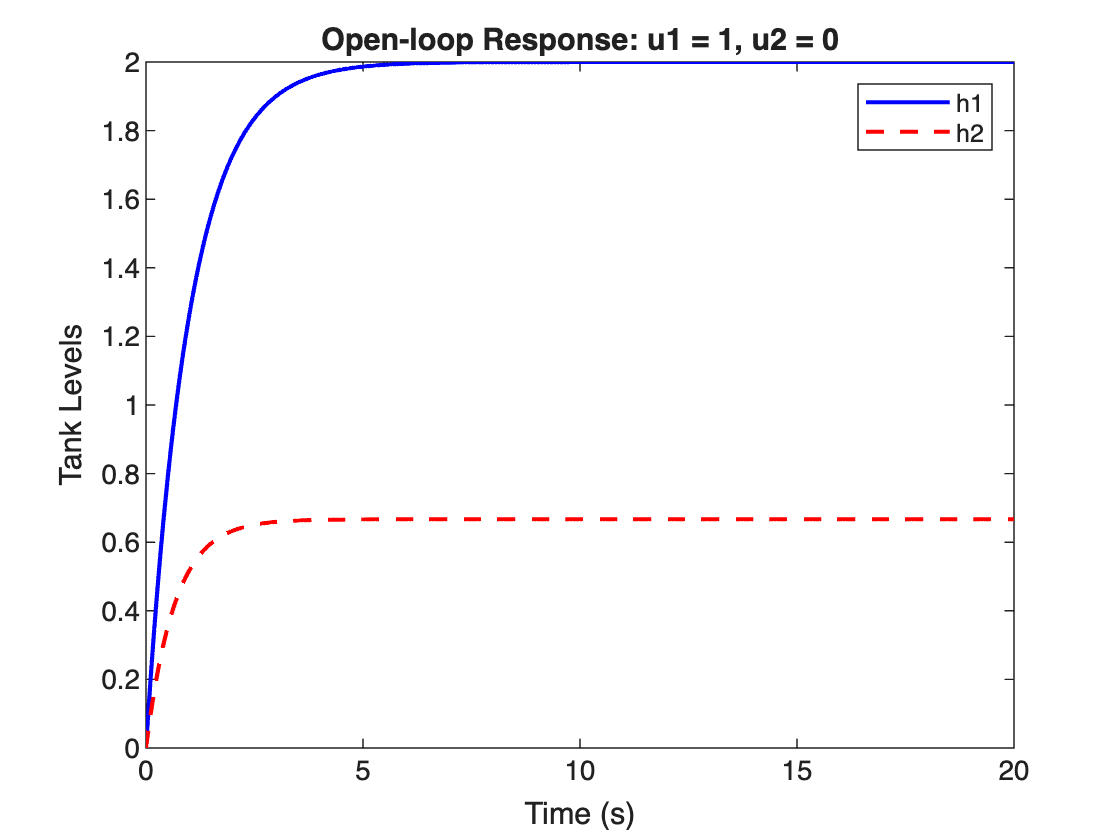

%% Problem 4: Simple MIMO System Control (a, b, c, d)

clc; clear; close all;

%% Define MIMO Plant (Continuous-Time)
G11 = tf(2, [1 1]);
G12 = tf(0.5, [1 2]);
G21 = tf(1, [1 1.5]);
G22 = tf(3, [1 1]);

G = [G11 G12; G21 G22];

%% Time Settings
dt = 0.01;
t  = 0:dt:20;

%% ===================== (a) Open-loop MIMO Analysis =====================

% Case 1: u1 = 1, u2 = 0
u1 = ones(length(t),1);
u2 = zeros(length(t),1);
u  = [u1 u2];

[y1, ~] = lsim(G, u, t);

figure;
plot(t, y1(:,1),'b', t, y1(:,2),'r--','LineWidth',1.5);
legend('h1','h2');
title('Open-loop Response: u1 = 1, u2 = 0');
xlabel('Time (s)'); ylabel('Tank Levels');

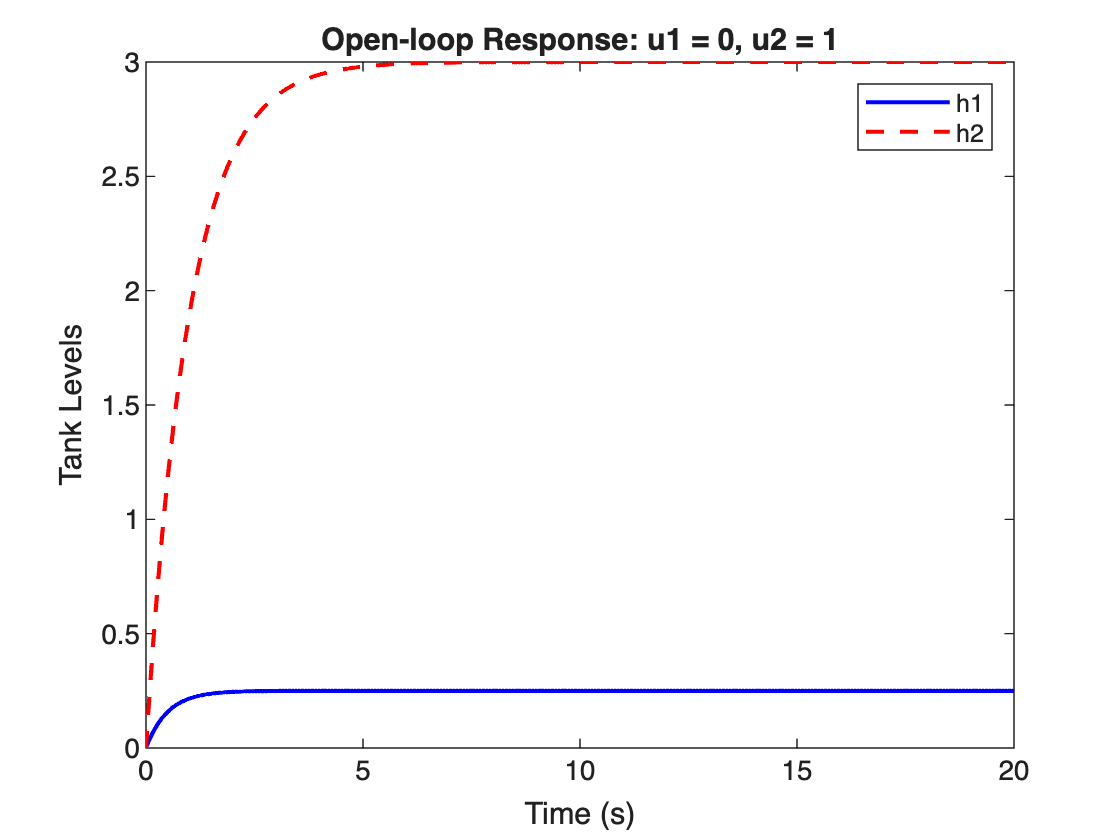


% Case 2: u1 = 0, u2 = 1
u1 = zeros(length(t),1);
u2 = ones(length(t),1);
u  = [u1 u2];

[y2, ~] = lsim(G, u, t);

figure;
plot(t, y2(:,1),'b', t, y2(:,2),'r--','LineWidth',1.5);
legend('h1','h2');
title('Open-loop Response: u1 = 0, u2 = 1');
xlabel('Time (s)'); ylabel('Tank Levels');

In a MIMO system, each output is not influenced by a single input alone, but by a combination of all system inputs. This behavior is captured by the MIMO transfer function matrix, where each element represents how a particular input affects a particular output.

For the given two-tank system, the outputs are described as:

h_1(s)=G_11(s)u_1(s)+G_12(s)u_2(s)

h_2(s)=G_21(s)u_1(s)+G_22(s)u_2(s)

This means that each output depends on **both inputs**, not just one.

When a step input is applied to u1� while keeping u2�=0, the output h1� increases mainly due to the direct transfer function G11(s). However, at the same time, the output h2 also changes because u1� is multiplied by the cross-coupling transfer function G21�(s).

Similarly, when a step input is applied to u2 while keeping u1�=0, the output h2 responds primarily through the direct transfer function G22(s). However, the output h1� also responds due to the cross-coupling term G12�(s).

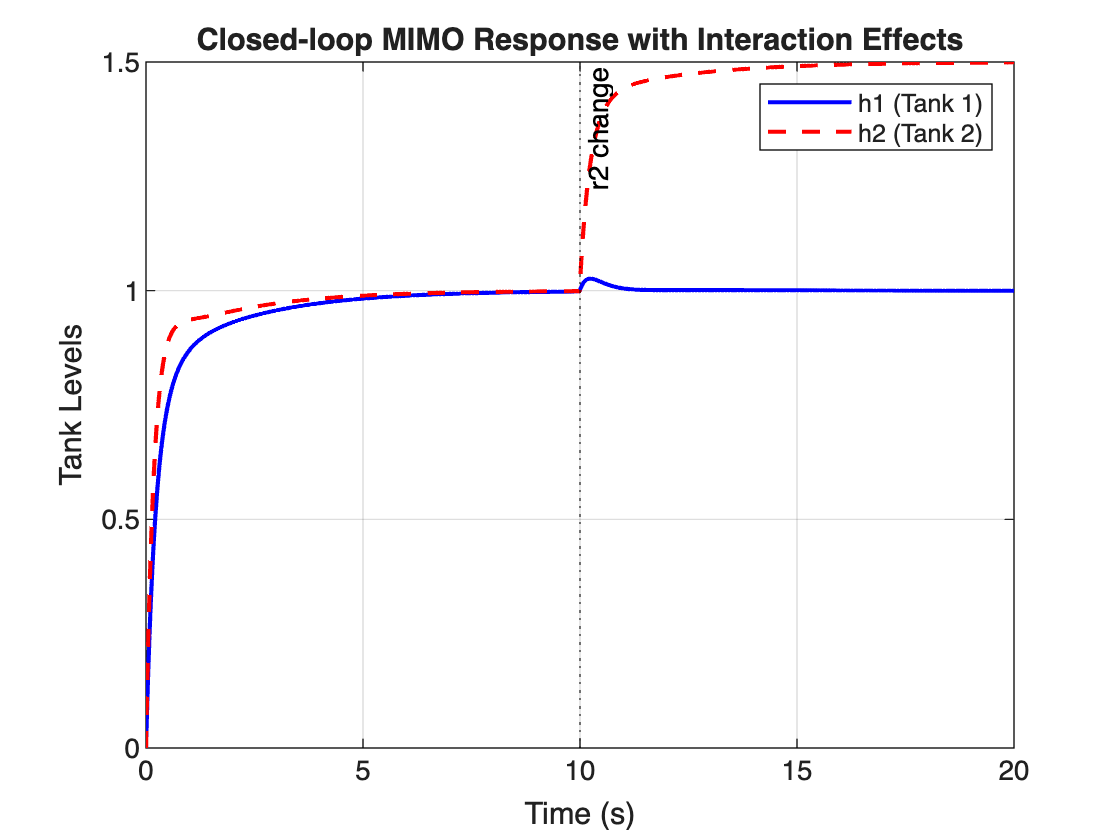


%% ================= (b) Decentralized PI Control =================
%% ============== (c) Interaction Effects =========================
%% ============== (d) Sequential Setpoint Change ==================

% References
r1 = ones(size(t))*1.0;        % Constant reference for Tank 1
r2 = ones(size(t))*1.0;        % Tank 2 reference changes at t = 10
r2(t >= 10) = 1.5;

% Initialize signals
h1 = zeros(size(t));
h2 = zeros(size(t));
u1 = zeros(size(t));
u2 = zeros(size(t));

% PI gains
Kp1 = 1.5; Ki1 = 0.8;
Kp2 = 1.2; Ki2 = 0.6;

% Integrators
e1_int = 0;
e2_int = 0;

%% Convert MIMO Plant Properly (State-Space → Discrete)
Gss = ss(G);          % Continuous-time state-space
Gd  = c2d(Gss, dt);   % Discrete-time state-space

% Initialize state vector
x = zeros(size(Gd.A,1),1);

%% Closed-loop Simulation
for i = 2:length(t)

    % Errors
    e1 = r1(i) - h1(i-1);
    e2 = r2(i) - h2(i-1);

    % PI controllers (decentralized)
    u1(i) = Kp1*e1 + Ki1*e1_int;
    u2(i) = Kp2*e2 + Ki2*e2_int;

    % Integrator updates
    e1_int = e1_int + e1*dt;
    e2_int = e2_int + e2*dt;

    % Input vector
    u_vec = [u1(i); u2(i)];

    % Discrete-time state update
    x = Gd.A*x + Gd.B*u_vec;

    % Output equation
    y = Gd.C*x + Gd.D*u_vec;

    h1(i) = y(1);
    h2(i) = y(2);
end

%% Plot Closed-loop Outputs (Interaction + Sequential Change)
figure;
plot(t,h1,'b','LineWidth',1.5); hold on;
plot(t,h2,'r--','LineWidth',1.5);
xline(10,'k:','r2 change');
legend('h1 (Tank 1)','h2 (Tank 2)');
xlabel('Time (s)');
ylabel('Tank Levels');
title('Closed-loop MIMO Response with Interaction Effects');
grid on;


%% Plot Control Inputs
figure;
plot(t,u1,'b','LineWidth',1.5); hold on;
plot(t,u2,'r--','LineWidth',1.5);
xline(10,'k:');
legend('u1','u2');
xlabel('Time (s)');
ylabel('Control Inputs');
title('Control Signals (Decentralized PI)');
grid on;

% Final values
h1_final = h1(end);
h2_final = h2(end);

% Settling time calculation (2% criterion)
tol1 = 0.02 * h1_final;
tol2 = 0.02 * h2_final;

idx1 = find(abs(h1 - h1_final) <= tol1, 1);
idx2 = find(abs(h2 - h2_final) <= tol2, 1);

Ts_h1 = t(idx1);
Ts_h2 = t(idx2);

%% Create table
ResultsTable = table( ...
    [h1_final; h2_final], ...
    [Ts_h1; Ts_h2], ...
    'VariableNames', {'FinalValue','SettlingTime_s'}, ...
    'RowNames', {'Tank1_h1','Tank2_h2'} );

disp('Closed-loop Performance Summary:');

Closed-loop Performance Summary:


disp(ResultsTable);

                FinalValue    SettlingTime_s
                __________    ______________

    Tank1_h1      1.0001           4.71     
    Tank2_h2      1.4989          12.13     



From the closed-loop response of the decentralized PI-controlled MIMO system, clear interaction effects can be observed.

**Effect of controlling** h1 **on** h2**:**

Yes, controlling h1 affects h2. Changes in the control input u1, which is used to regulate Tank 1, also influence the level of Tank 2. This occurs due to the cross-coupling term in the plant, where input u1 has a direct effect on output h2.

**Interference between outputs:**

The outputs do interfere with each other. When one tank level is corrected by its controller, the other tank experiences a transient disturbance. This indicates that the two control loops are not independent and that interaction is present in the system.

**Overshoot or oscillation due to interaction:**

A small amount of overshoot and transient deviation is observed in both tank levels. However, no sustained oscillations occur. The PI controllers are able to stabilize the system, but the interaction between loops slightly degrades the transient performance by increasing settling time.

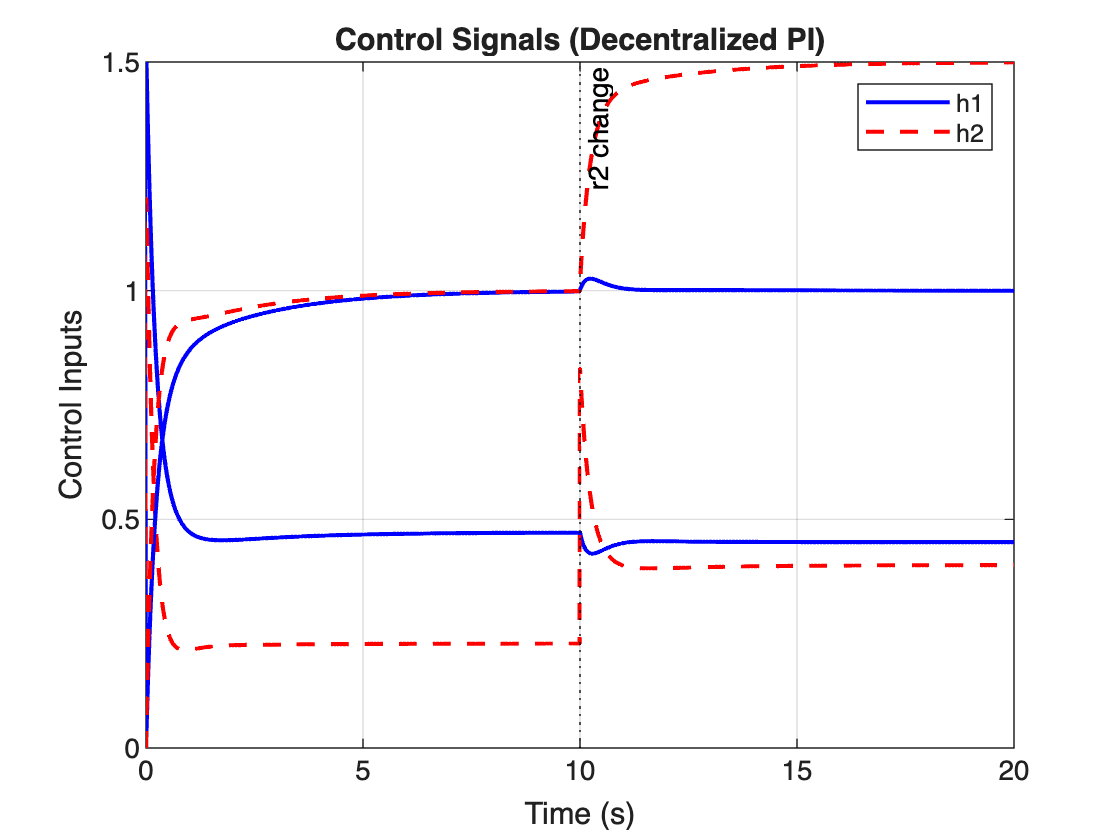

r1 = ones(size(t))*1.0;        % r1 = 1.0 for all time

r2 = ones(size(t))*1.0;        % r2 = 1.0 initially
r2(t >= 10) = 1.5;             % r2 changes at t = 10 s
e1 = r1(i) - h1(i-1);
e2 = r2(i) - h2(i-1);
plot(t,h1,'b',t,h2,'r--','LineWidth',1.5); hold on;
xline(10,'k:','r2 change');
legend('h1','h2');

MIMO systems are more difficult to control than SISO systems because each input affects multiple outputs. As a result, a change in one control loop can disturb other outputs, even if their references remain unchanged. This interaction makes controller tuning more complex and can degrade transient performance.

**SUGGESTION**:

A possible improvement is to reduce this interaction so that each controller mainly influences its own tank.

**Summary Questions**

**After completing all problems, answer these briefly:**

**1. When would you choose a lead compensator over increasing PID gains?**

A lead compensator is chosen when faster transient response and improved stability margins are required without significantly increasing overshoot or noise sensitivity. Increasing PID gains alone can make the system unstable or overly sensitive to noise.

**2. What are the main advantages and limitations of lag compensators?**

Lag compensators improve steady-state accuracy by reducing steady-state error and increasing low-frequency gain. However, they slow down the system response and can increase settling time.

**3. Why is feedforward control called ”proactive” compared to feedback?**

Feedforward control is called proactive because it acts in anticipation of known disturbances or reference changes before they affect the system output, whereas feedback reacts only after an error has occurred.

**4. What makes MIMO systems more difficult to control than SISO systems?**

MIMO systems are more difficult to control because each input affects multiple outputs, causing interaction between control loops. These interactions make controller design and tuning more complex compared to independent SISO systems.